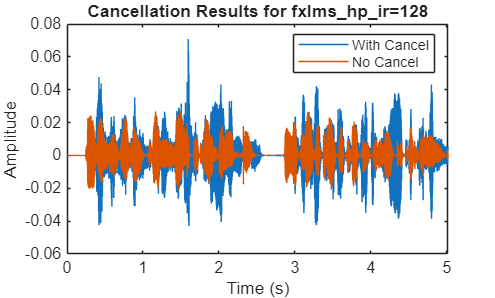

c1_128 = CancelAnalysis('fxlms_hp_ir=128');
c1_128.plot_cancel_results();

[c1_128_diff, ~, nc_rms] = c1_128.rms_diff();

Cancel RMS is 0.003745 greater than no-cancel RMS
Cancel RMS: 0.0081
No-cancel RMS: 0.0043


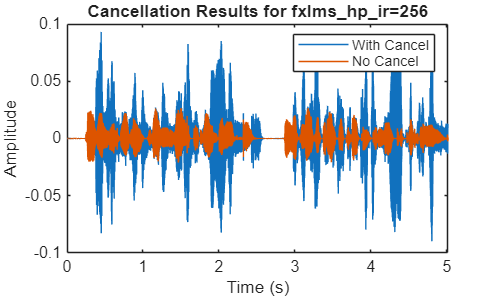

c1_256 = CancelAnalysis('fxlms_hp_ir=256');
c1_256.plot_cancel_results();

[c1_256_diff, ~, ~] = c1_256.rms_diff();

Cancel RMS is 0.011705 greater than no-cancel RMS
Cancel RMS: 0.0161
No-cancel RMS: 0.0043


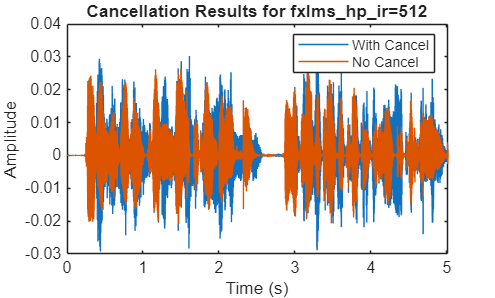

c1_512 = CancelAnalysis('fxlms_hp_ir=512');
c1_512.plot_cancel_results();

[c1_512_diff, ~, ~] = c1_512.rms_diff();

Cancel RMS is 0.001310 greater than no-cancel RMS
Cancel RMS: 0.0057
No-cancel RMS: 0.0043


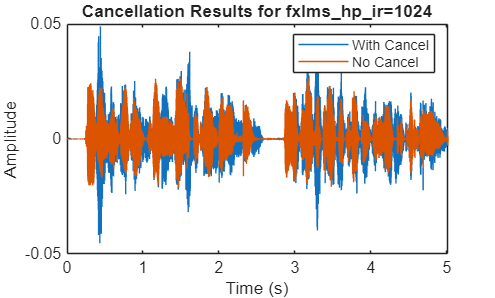

c1_1024 = CancelAnalysis('fxlms_hp_ir=1024');
c1_1024.plot_cancel_results();

[c1_1024_diff, ~, ~] = c1_1024.rms_diff();

Cancel RMS is 0.001462 greater than no-cancel RMS
Cancel RMS: 0.0058
No-cancel RMS: 0.0043


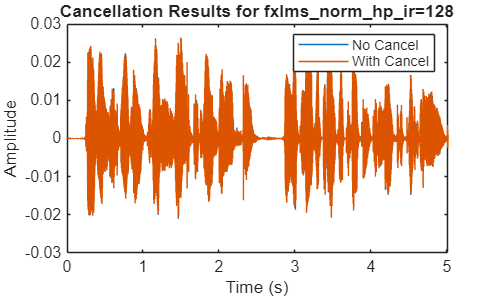

c2_128 = CancelAnalysis('fxlms_norm_hp_ir=128');
c2_128.plot_cancel_results();

[c2_128_diff, ~, ~] = c2_128.rms_diff();

Cancel RMS is 0.000019 less than no-cancel RMS
Cancel RMS: 0.0043
No-cancel RMS: 0.0043


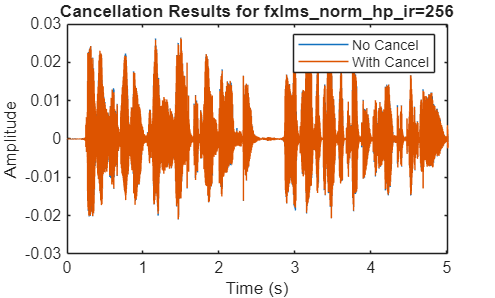

c2_256 = CancelAnalysis('fxlms_norm_hp_ir=256');
c2_256.plot_cancel_results();

[c2_256_diff, ~, ~] = c2_256.rms_diff();

Cancel RMS is 0.000023 less than no-cancel RMS
Cancel RMS: 0.0043
No-cancel RMS: 0.0043


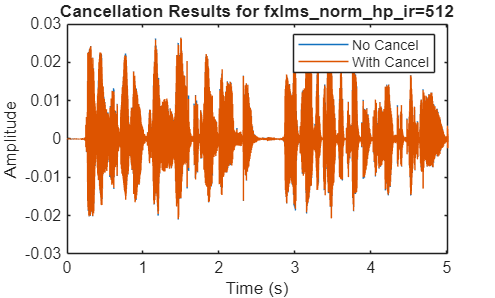

c2_512 = CancelAnalysis('fxlms_norm_hp_ir=512');
c2_512.plot_cancel_results();

[c2_512_diff, ~, ~] = c2_512.rms_diff();

Cancel RMS is 0.000025 less than no-cancel RMS
Cancel RMS: 0.0043
No-cancel RMS: 0.0043


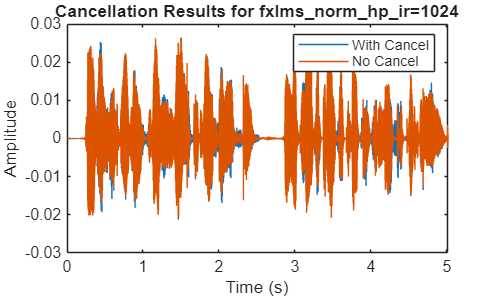

c2_1024 = CancelAnalysis('fxlms_norm_hp_ir=1024');
c2_1024.plot_cancel_results();

[c2_1024_diff, ~, ~] = c2_1024.rms_diff();

Cancel RMS is 0.000061 greater than no-cancel RMS
Cancel RMS: 0.0044
No-cancel RMS: 0.0043


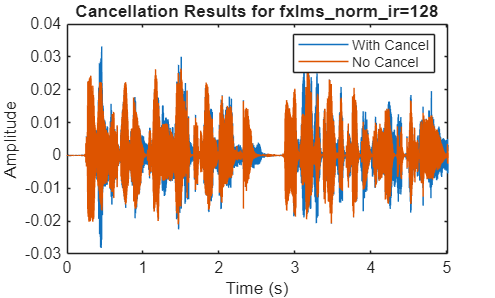

c3_128 = CancelAnalysis('fxlms_norm_ir=128');
c3_128.plot_cancel_results();

[c3_128_diff, ~, ~] = c3_128.rms_diff();

Cancel RMS is 0.000483 greater than no-cancel RMS
Cancel RMS: 0.0048
No-cancel RMS: 0.0043


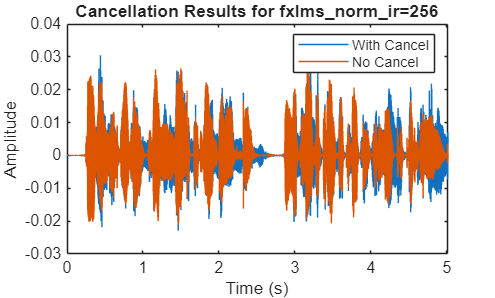

c3_256 = CancelAnalysis('fxlms_norm_ir=256');
c3_256.plot_cancel_results();

[c3_256_diff, ~, ~] = c3_256.rms_diff();

Cancel RMS is 0.000708 greater than no-cancel RMS
Cancel RMS: 0.0051
No-cancel RMS: 0.0043


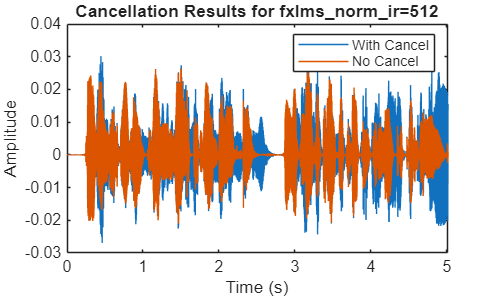

c3_512 = CancelAnalysis('fxlms_norm_ir=512');
c3_512.plot_cancel_results();

[c3_512_diff, ~, ~] = c3_512.rms_diff();

Cancel RMS is 0.001766 greater than no-cancel RMS
Cancel RMS: 0.0061
No-cancel RMS: 0.0043


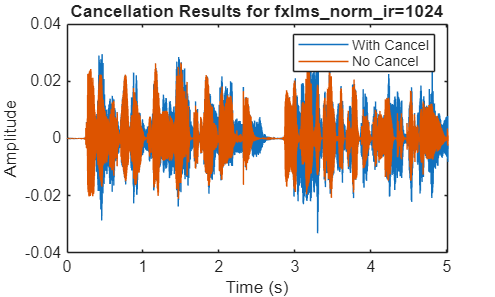

c3_1024 = CancelAnalysis('fxlms_norm_ir=1024');
c3_1024.plot_cancel_results();

[c3_1024_diff, ~, ~] = c3_1024.rms_diff();

Cancel RMS is 0.001388 greater than no-cancel RMS
Cancel RMS: 0.0057
No-cancel RMS: 0.0043


hp_diff = [c1_128_diff, c1_256_diff, c1_512_diff, c1_1024_diff];
norm_hp_diff = [c2_128_diff, c2_256_diff, c2_512_diff, c2_1024_diff];
norm_diff = [c3_128_diff, c3_256_diff, c3_512_diff, c3_1024_diff];
ir_pow2 = [7, 8, 9, 10];

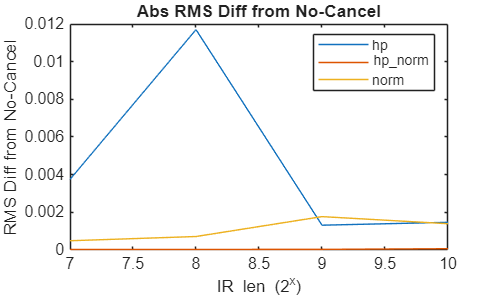

figure
plot(ir_pow2, hp_diff)
hold on
plot(ir_pow2, norm_hp_diff)
hold on
plot(ir_pow2, norm_diff)
hold off

legend("hp", "hp\_norm", "norm")
title("Abs RMS Diff from No-Cancel")
xlabel("IR len (2^x)")
ylabel("RMS Diff from No-Cancel")
xlim([ir_pow2(1), ir_pow2(end)])